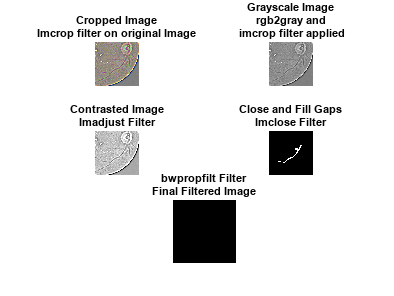

0 possible spots identified at ok #1.ppm. Eye is normal


close all
clc
Normal = 0;
Diagnosed=0;
%
for i = 1:1
    I = imread('C:\Users\Shubham Mishra\Documents\MATLAB\ok1.ppm.png');     % Image read
    I_crop = imcrop(I,[95, 95, 500, 410]);    % Image cropped
    I2 = rgb2gray(I_crop);                    % Image converted to gray level image
    I_adjusted = imadjust(I2, [0.2 0.7], [0 1], 0.8);   % The density of the image has been adjusted.
    I_contrast = adapthisteq(I_adjusted, 'numTiles', [8 8], 'nBins', 28);   %The contrast of the image has been adjusted
    meanfilt = fspecial('average', [90, 90]);     % Average filter defined
    mask_mean = imfilter(I_contrast, meanfilt);   
    mask_mean2 = imsubtract(mask_mean, I_contrast); % The contrast-adjusted image passed through the % Average filter is removed from the filter and detected by edge...
    ...done
    mask_binarize = imbinarize(mask_mean2, 'adaptive', 'ForegroundPolarity','dark','Sensitivity',0.6);  % Görüntü siyah-beyaz 'a çevrildi.
    bw = bwareaopen(mask_binarize, 100);  
    se = strel('disk',2);   
    bw = imclose(bw,se);
    CC = bwconncomp(bw);    % Connected graph components,We keep the properties of the image in a struct. (Connectivity, ImageSize, NumObjects, PixelIdxList)

    numPixels = cellfun(@numel, CC.PixelIdxList);  
    [biggest, idx] = max(numPixels);  
    bw(CC.PixelIdxList{idx}) = 0;     
    cc_1 =bwconncomp(bw, 26);  %It recreates the image containing the object whose largest object has been deleted, with a connectivity feature of 26 and...
    ...collects the properties of this image into a struct
    RemoveVessels = bwpropfilt(bw, 'Eccentricity', [0, .9]);  % Siyah-beyaz level görüntüden obje çıkartır. Görüntüde hala damar varsa bunlar kaldırılır.
    figure(i)    
    subplot(3,2,1) 
    imshow(I_crop, 'Border', 'tight')
    title({'Cropped Image','Imcrop filter on original Image'})
    subplot(3,2,2)
    imshow(I2, 'Border', 'tight')
    title({'Grayscale Image','rgb2gray and',' imcrop filter applied'})
    subplot(3,2,3)
    imshow(I_adjusted, 'Border', 'tight')
    title({'Contrasted Image','Imadjust Filter'})
    subplot(3,2,4)
    imshow(bw)
    title({'Close and Fill Gaps','Imclose Filter'})
    % Plot the image with most blood vessels removed.
    subplot(3,2,[5 6])
    imshow(RemoveVessels)
    title({'bwpropfilt Filter','Final Filtered Image'})
    centroid_dataV = regionprops(RemoveVessels,'Centroid');  % The bubbles in the image and their centers were obtained and this information was kept in a struct.
    NumberBlobs = length(centroid_dataV);    % Obtained from the length (number of elements) of the struct.
    if NumberBlobs <= 5    % If the number of bubbles is less than or equal to 5, the eye is healthy.
        fprintf('%d possible spots identified at ok #%d.ppm. Eye is normal\n', NumberBlobs, i);
        Normal = Normal+1;
    else                   % If the number of bubbles is greater than 5, the eye is diseased.
        Diagnosed = Diagnosed +1;
        fprintf('%d possible spots identified in ok #%d.ppm. Diabetic Retinopathy Symptoms Detected\n', NumberBlobs, i);
    end
    i=i+1;
end

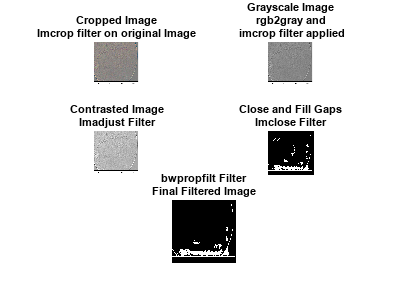

4 possible spots identified at ok #11.ppm. Diabetic Retinopathy Symptoms Detected


% Repeat the same steps for photos of diseased retinas.
for i = 1:1
    I = imread('C:\Users\Shubham Mishra\MATLAB\detected.ppm.png');     
    I_crop = imcrop(I,[95, 95, 500, 410]);    
    I2 = rgb2gray(I_crop);                    
    I_adjusted = imadjust(I2, [0.2 0.7], [0 1], 0.8);
    I_contrast = adapthisteq(I_adjusted, 'numTiles', [8 8], 'nBins', 28);   
    meanfilt = fspecial('average', [90, 90]);     
    mask_mean = imfilter(I_contrast, meanfilt);   
    mask_mean2 = imsubtract(mask_mean, I_contrast);  
    mask_binarize = imbinarize(mask_mean2, 'adaptive', 'ForegroundPolarity','dark','Sensitivity',0.6);
    bw = bwareaopen(mask_binarize, 100);  
    se = strel('disk',2);   
    bw = imclose(bw,se);    
    CC = bwconncomp(bw);    
    numPixels = cellfun(@numel, CC.PixelIdxList);  
    [biggest, idx] = max(numPixels);    
    bw(CC.PixelIdxList{idx}) = 0;       
    cc_1 =bwconncomp(bw, 26);           
    RemoveVessels = bwpropfilt(bw, 'Eccentricity', [0, .9]);  
    figure(i+10)
    subplot(3,2,1)  
    imshow(I_crop, 'Border', 'tight')
    title({'Cropped Image','Imcrop filter on original Image'})
    subplot(3,2,2)
    imshow(I2, 'Border', 'tight')
    title({'Grayscale Image','rgb2gray and',' imcrop filter applied'})
    subplot(3,2,3)
    imshow(I_adjusted, 'Border', 'tight')
    title({'Contrasted Image','Imadjust Filter'})
    subplot(3,2,4)
    imshow(bw)
    title({'Close and Fill Gaps','Imclose Filter'})
    % Plot the image with most blood vessels removed.
    subplot(3,2,[5 6])
    imshow(RemoveVessels)
    title({'bwpropfilt Filter','Final Filtered Image'})
    centroid_dataV = regionprops(RemoveVessels,'Centroid');   
    NumberBlobs = length(centroid_dataV);                     
    if NumberBlobs <= 5       
        fprintf('%d possible spots identified at ok #%d.ppm. Diabetic Retinopathy Symptoms Detected\n', NumberBlobs, i+10);
        Normal = Normal+1;     
    else
        Diagnosed = Diagnosed +1;
        fprintf('%d possible spots identified in ok #%d.ppm. Diabetic Retinopathy Symptoms Detected\n', NumberBlobs, i+10);
    end
  i=i+1;  
end